# MATLAB Refresher

#### Created by the UQ Mathematics Students Society (MSS)

This is a quick guide to refresh your MATLAB skills. We'll be covering basic mathematical operations, vectors and matrices, plotting functions, plotting surfaces and hopefully some ODE solvers. Whilst there is a tutor to help guide you through, feel free to go ahead at your own pace. If you have any questions or difficulties at any point, please raise your hand and we'll try to help.

The main project that we'll focus on is a simulation of a ball being thrown. We'll start with calculating the target location manually, and hopefully end up with a basic simulation using ODE solvers.

## How to Run Code

We're in a Matlab Live Script, so things might be a little different to usual. To run a section of code, either click `Run Section` from the toolstrip up the top (under the tab `Live Editor`), or you can click on the blue ribbon in the left margin.

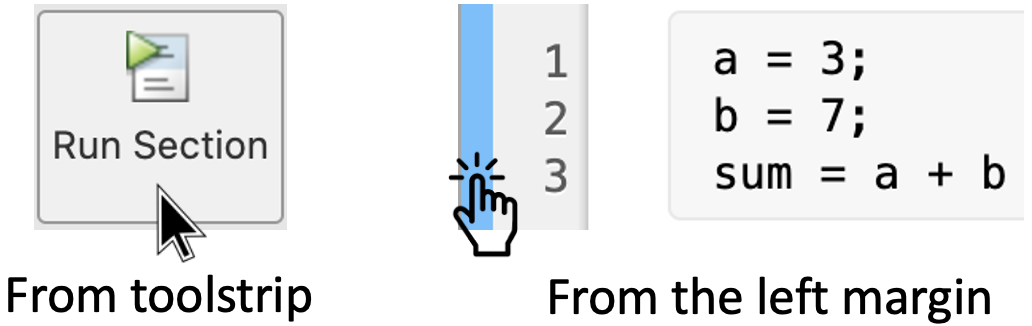

## 1. Basic Mathematical Operations

MATLAB is mathematical in its very nature, so it is easy to do all sorts of calculations. First, we'll learn how to use MATLAB as a basic calculator.

The four basic operations of addition, subtraction, multiplication, and division are written with a `+`, `-`, `*`, and `/` respectively.

1 + 2 % Expected: 3

ans = 3

6 - 4 % Expected: 2

ans = 2

5 * 10 % Expected: 50

ans = 50

16 / 5 % Expected: 3.2

ans = 3.2000

The green text after the `%` on each line are **comments**, and are used to explain code. MATLAB pretends comments don't exist when running code, so you can type whatever you want in them! They are very useful to help other people understand your code, so please use them when you can!

MATLAB also has some other in-built functions, such as exponentiation (both `^` and `exp(...)` work), sine `sin(...)` and cosine `cos(...)`, and square roots `sqrt(...)`.

4 ^ 2 % Expected: 16

ans = 16

exp(1) % Expected: 2.718

ans = 2.7183

sin(0) % Expected: 0

ans = 0

cos(pi) % Expected: -1

ans = -1

sqrt(25) % Expected: 5

ans = 5

The order of operations is very important for MATLAB! By default, MATLAB will evaluate expressions using the standard order of operations. You may need to insert brackets to get your desired output.

2 - 4 + 1 % Expected: -1

ans = -1

2 - (4 + 1) % Expected: -3

ans = -3

You may have seen above that MATLAB has some constants pre-defined (such as `pi`). Here are some examples.

pi

ans = 3.1416

i

ans = 0.0000 + 1.0000i

inf

ans = Inf

% Notice that e is missing! How else can we get the value of e?

What if we want to define our own named constants? Not to worry! This is the role of variables.

## 2. Variables

A **variable** is a way to store data in MATLAB. All variables have a name, which may consist of letters, numbers, and underscores (but must start with a letter).

To define a variable, we use the code `variable_name = <value>`. This code creates a new variable, called `variable_name`, and stores `<value>` inside of it. For example,

e = exp(1); % The semicolon at the end of the line suppresses the output. See what happens when you remove it!

To access the value of the variable, simply type its name.

e

e = 2.7183

We can define variables in terms of other variables, and even perform operations on them!

my_favourite_number = 4 + 5 * (2 + 1)

my_favourite_number = 19

bad_number = 3 / 2

bad_number = 1.5000

my_new_favourite_number = (my_favourite_number - 10) / bad_number

my_new_favourite_number = 6

While this is all very fun, we need to make sure that the variables we access have already been defined. If not, MATLAB will throw an error.

k = 1;
b = 2;

c = 3; % Fixed!
k + b * c % This throws an error! How can we fix it?

ans = 7

## *Your turn!*

Let's start building up our model of a ball being thrown.

Create three variables: the gravitational acceleration `g` (equal to 9.8), the initial velocity in the x direction `initial_x_velocity` (equal to 3), and the initial velocity in the y direction `initial_y_velocity` (equal to 4.905).

% Write your code here!
g = 9.8;
initial_x_velocity = 3;
initial_y_velocity = 4.905;

We can use these variables to calculate some useful properties of our ball. The maximum height of a projectile is given by $y_{\max } =\frac{u_y^2 }{2g}$, and the angle that the ball is thrown at is given by $\theta =\arctan \left(\frac{u_y }{u_x }\right)$, where $u_x$ and $u_y$ are the initial velocities in the x and y directions respectively. 

Using the above variables, calculate the maximum height of the ball and the angle it is thrown at. *Hint:* MATLAB uses `atan(...)` for $\arctan(\dots)$. If you want your answer in degrees, use `atand(...)`.

maximum_height = initial_y_velocity ^ 2 / (2 * g)

maximum_height = 1.2275

throw_angle = atan(initial_y_velocity / initial_x_velocity)

throw_angle = 1.0219

Run the code in this section and see how you went!

####         (Expected answers: `maximum_height = 1.2275`, `throw_angle = 1.0219` or `58.5492` degrees)

## 3. Vectors and Matrices

MATLAB was specifically made for handling matrices (hence the name "MATrix LABoratory"). It is one of the fastest and most adaptable programming languages for most matrix operations. Variables can be assigned vectors and matrices, not just numbers!

There are lots of different ways to create vectors and matrices. The first way is to explicitly write out the entries in the vector or matrix. This is done by using *square brackets*. Commas (or spaces) give us a row vector, semicolons give us a column vector, and matrices can be written in this way too! To change between row and column vectors, we use the transpose `'`. This transpose also works for matrices!

small_primes = [2, 3, 5, 7] % This is a row vector

small_primes =      2     3     5     7



larger_primes = [11 13 17 19] % This is also a row vector

larger_primes =     11    13    17    19



composites_column = [4; 6; 8; 9] % This is a column vector

composites_column =      4
     6
     8
     9



small_matrix = [1, 2; 3, 4] % This is a matrix - it's a column vector of row vectors!

small_matrix =      1     2
     3     4



magic_square = [
    8 1 6
    3 5 7
    4 9 2
] % This is a bigger matrix. Notice how we can format it nicely

magic_square =      8     1     6
     3     5     7
     4     9     2



composites_row = composites_column' % The dash transposes vectors and matrices

composites_row =      4     6     8     9



other_square = magic_square'

other_square =      8     3     4
     1     5     9
     6     7     2


However, writing out every element of a matrix can be hard work (especially if the matrix has thousands of elements!). MATLAB gives us some shortcuts to define common vectors. The first is the **colon operator**, which allows us create vectors with regularly-spaced entries.

steps = 1:5 % The colon fills in all the integers in between the endpoints. This is equivalent to [1 2 3 4 5]

steps =      1     2     3     4     5



smaller_steps = 1:0.5:5 % We can also change the step size

smaller_steps =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


Next is the `linspace` command, which also allows us to create vectors with evenly-spaced entries. The difference between the colon operator and `linspace` is that the colon operator allows us to control the step size between elements, while `linspace` allows us to control the number of elements in the vector.

steps2 = linspace(0, 3, 5) % This produces 5 numbers, evenly spaced between 0 and 3

steps2 =          0    0.7500    1.5000    2.2500    3.0000



smaller_steps2 = linspace(0, 10, 1000) % This produces 1000 numbers, evenly spaced between 0 and 10

smaller_steps2 =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


Very similar to the `linspace` command is the `meshgrid` command, which creates matrices out of two vectors. It outputs two matrices: one where the numbers increase horizontally, and the other where the numbers increase vertically.

[X, Y] = meshgrid(1:10, 1:10) % Notice how the inputs to meshgrid are vectors!

X =      1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10


Y =      1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9
    10    10    10    10    10    10    10    10    10    10



[Xnew, Ynew] = meshgrid(1:10, 1:5) % Different sized inputs

Xnew =      1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10
     1     2     3     4     5     6     7     8     9    10


Ynew =      1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5


Finally, we can combine vectors and matrices together.

all_primes = [small_primes, larger_primes] % We can combine vectors and matrices like this

all_primes =      2     3     5     7    11    13    17    19



prime_table = [small_primes; larger_primes] % We can also combine them vertically

prime_table =      2     3     5     7
    11    13    17    19


#### Note: MATLAB sees vectors as just matrices with only one row or one column, so anything that works on a matrix will work on a vector.

In order to access elements of a vector or matrix, we use *round brackets*. Note that MATLAB is *one-indexed* (unlike most other programming languages), which means that the first element is entry 1, not entry 0.

small_primes(1) % First element of vector

ans = 2

small_matrix(2, 1) % Entry of matrix in second row, first column

ans = 3

We can use the colon operator to retrieve multiple elements of a vector or matrix. Including just a colon with no endpoints will retrieve every element. This is called **colon-indexing**.

larger_primes(1:3) % Elements 1-3 of vector

ans =     11    13    17


all_primes(1:2:8) % Get every odd element of vector

ans =      2     5    11    17


X(1:3, 2:4) % Get entries from 1st-3rd row and 2nd-4th column of matrix

ans =      2     3     4
     2     3     4
     2     3     4


Ynew(:, 1) % Get every element of the 1st column of matrix

ans =      1
     2
     3
     4
     5


One last thing: to find the index of a certain number in a vector or matrix, we can use the `find` command. The syntax is a little bit weird: `find(vector == x)` returns a vector containing every index that `x` appears in `vector`.

find(all_primes == 7) % Finds which index the number 7 appears in the all_primes vector

ans = 4

find([1 2 1 3 1 4] == 1) % 1 occurs multiple times in this vector

ans =      1     3     5


find(all_primes == 8) % 8 is not a prime, so MATLAB returns an empty vector


ans =

  1x0 empty double row vector



## 4. Matrix Operations and Vectorisation

Now that we have some matrices, we can use them in some calculations. We can add and subtract matrices, and multiply them by a scalar using the standard operations `+`, `-`, `*`.

% Remember,
% small_primes = [2 3 5 7]
% larger_primes = [11 13 17 19]
% steps = [1 2 3 4 5]

small_primes + larger_primes % Vector addition

ans =     13    16    22    26


small_primes - larger_primes % Vector subtraction

ans =     -9   -10   -12   -12


2 * steps % Multiplying a vector by a scalar

ans =      2     4     6     8    10


When working with matrices, we need to be very careful when using multiplication, division, and exponentiation. The expression `A * B` multiplies the matrices `A` and `B` together. In order to multiply each element in `A` by the corresponding element in `B`, we need to put a dot before the operation. This turns the operation into an **array operation**, where the operation is performed "element-wise" rather than as a matrix.

small_matrix ^ 2 % This is squared using matrix multiplication

ans =      7    10
    15    22


small_matrix .^ 2 % This squares each element individually

ans =      1     4
     9    16


One very important feature of MATLAB that sets it apart from other progamming languages is its ability to work with vector operations efficiently. In order to apply . However, in MATLAB, we . This is called **vectorisation**, and is much more efficient (and readable!) than loop-based code.

squares = [1 4 9 16 25];
square_roots = sqrt(squares) % This takes the square root of each element individually

square_roots =      1     2     3     4     5



pi_multiples = 0:pi:100 % Contains integer multiples of pi between 0 and 100

pi_multiples =          0    3.1416    6.2832    9.4248   12.5664   15.7080   18.8496   21.9911   25.1327   28.2743   31.4159   34.5575   37.6991   40.8407   43.9823   47.1239   50.2655   53.4071   56.5487   59.6903   62.8319   65.9734   69.1150   72.2566   75.3982   78.5398   81.6814   84.8230   87.9646   91.1062   94.2478   97.3894


cos_pi_multiples = cos(pi_multiples)

cos_pi_multiples =      1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1


sin_pi_multiples = sin(pi_multiples) % Uh oh... why isn't every element 0?

sin_pi_multiples = 1.0e-13 *

         0    0.0012   -0.0024    0.0037   -0.0049    0.0061   -0.0073    0.0086   -0.0098    0.0110   -0.0122    0.0490   -0.0147   -0.0196   -0.0171    0.0539   -0.0196    0.0563   -0.0931    0.0588   -0.0245   -0.0098   -0.0980    0.0637   -0.0294    0.1372   -0.1029    0.0686   -0.0343   -0.0000   -0.1078    0.0735


## *Your turn!*

That was a bit of a long side tour, but we now have the tools to calculate the ball's trajectory.

First we'll set up a range of points in time that we'll measure the ball's position at. Create a vector of 101 evenly spaced points in time between 0 and 1.

time_points = linspace(0, 1, 101);

Now we'll calculate the x and y positions over time. The formulae for the x and y position of a projectile are $x=u_xt$ and $y=-\frac{1}{2}gt^2+u_yt$. Implement them below. Remember that we will need to use the element-wise operations!

calculated_x = initial_x_velocity * time_points;

calculated_y = -1/2 * g * time_points .^ 2 + initial_y_velocity * time_points;

Finally, let's compare this to the maximum height we calculated earlier! Theoretically, this should occur at exactly half of the total flight time, which occurs at 0.5 seconds. Retrieve the maximum height from `calculated_y`. *Hint:* You might need to find the index of 0.5 in `time_points`.

maximum_height % Prints out previously calculated max height

maximum_height = 1.2275


calculated_maximum_height = calculated_y(find(time_points == 0.5))

calculated_maximum_height = 1.2275

       ** (Expected answer: the maximum height should match up with your calculation!)**

## 5. Plotting

One of the more useful features of MATLAB is its ability to construct plots. 

The most basic plot is a simple 2D plot of a function. MATLAB's `plot` command can do this for us. It takes two vectors as input - the x coordinates and y coordinates - and does a sort of "join the dots" to output a plot.

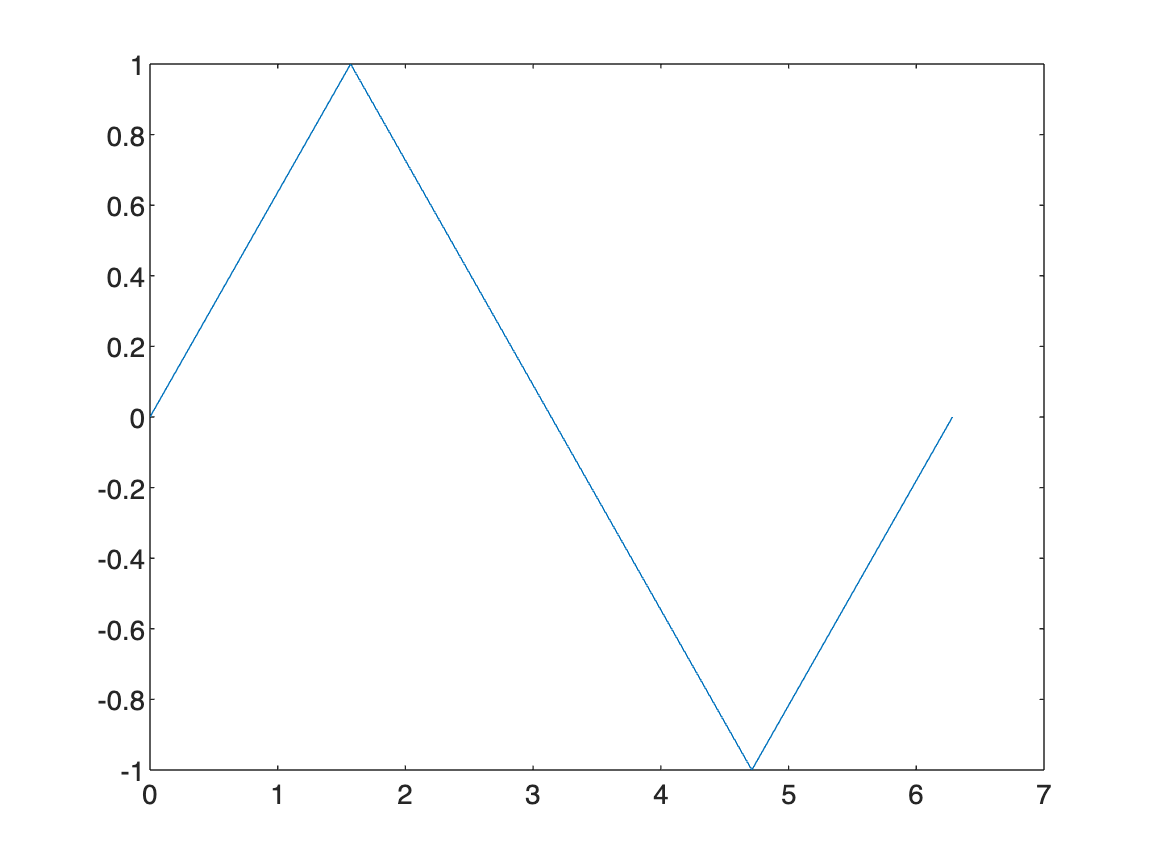

x = linspace(0,2*pi,5); % Create vector of x values from 0 to 2pi
y = sin(x); % Graph y = sin(x) on the domain [0, 2pi]
plot(x, y)

This plot isn't very good. It's bumpy and doesn't have a lot of detail. This is because we haven't included many sampling points in our `x` vector - there's only 5 points to "join the dots" with! If we increase the number of points, we can increase the quality of the graph.

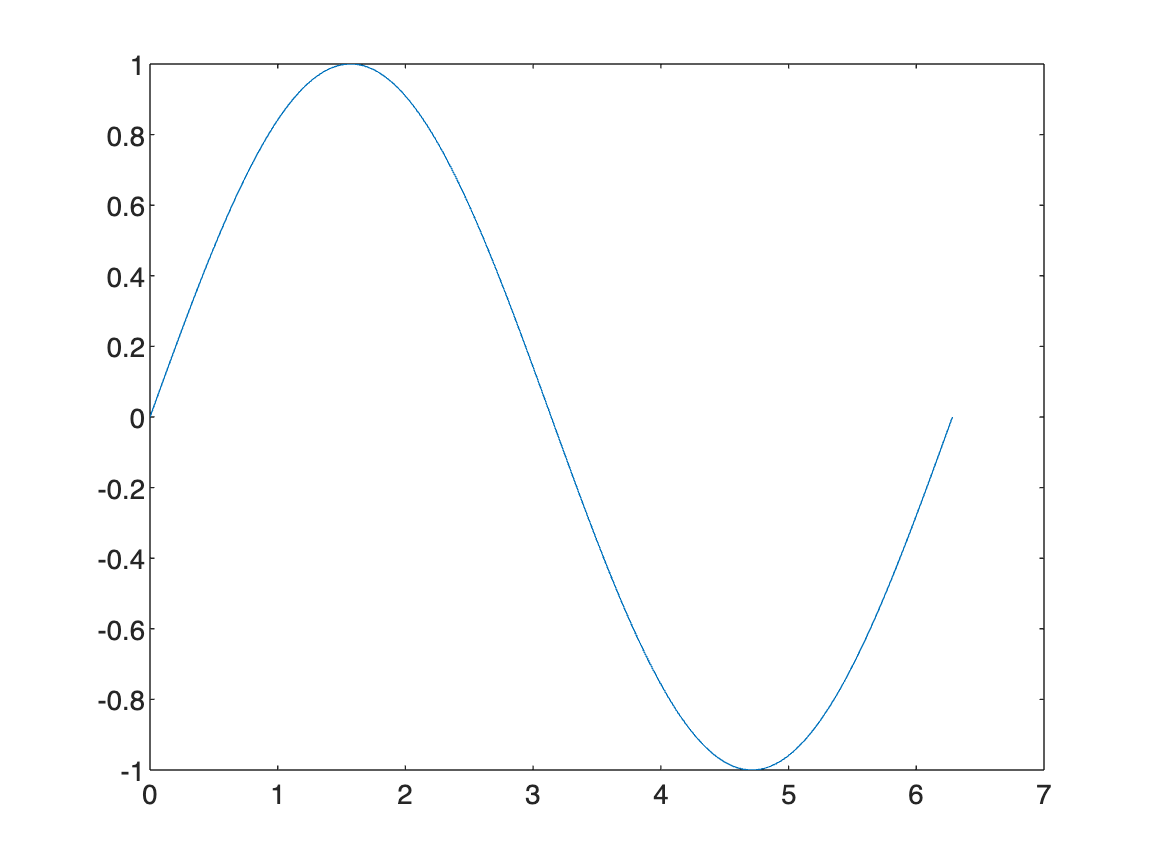

x = linspace(0,2*pi,1000); % Create better vector of x values
y = sin(x);
plot(x, y)

Notice how the graph looks a lot smoother!

MATLAB also allows us to customise the appearance of the plots we make. We can customise the colour of our line by specifying a colour code. Some common colours are:

        `r` red

        `b` blue

        `k` black

        `g` green

        `y` yellow

We can also customise the style of the line. Some examples are:

        `-` solid line

        `--` dashed line

        `:` dotted line

In order to change this setting, we need to include an extra input to the `plot` command. We put the style of the line, followed by the colour of the line, surrounded in quotation marks. The default setting is a solid blue line, or `"-b"`.

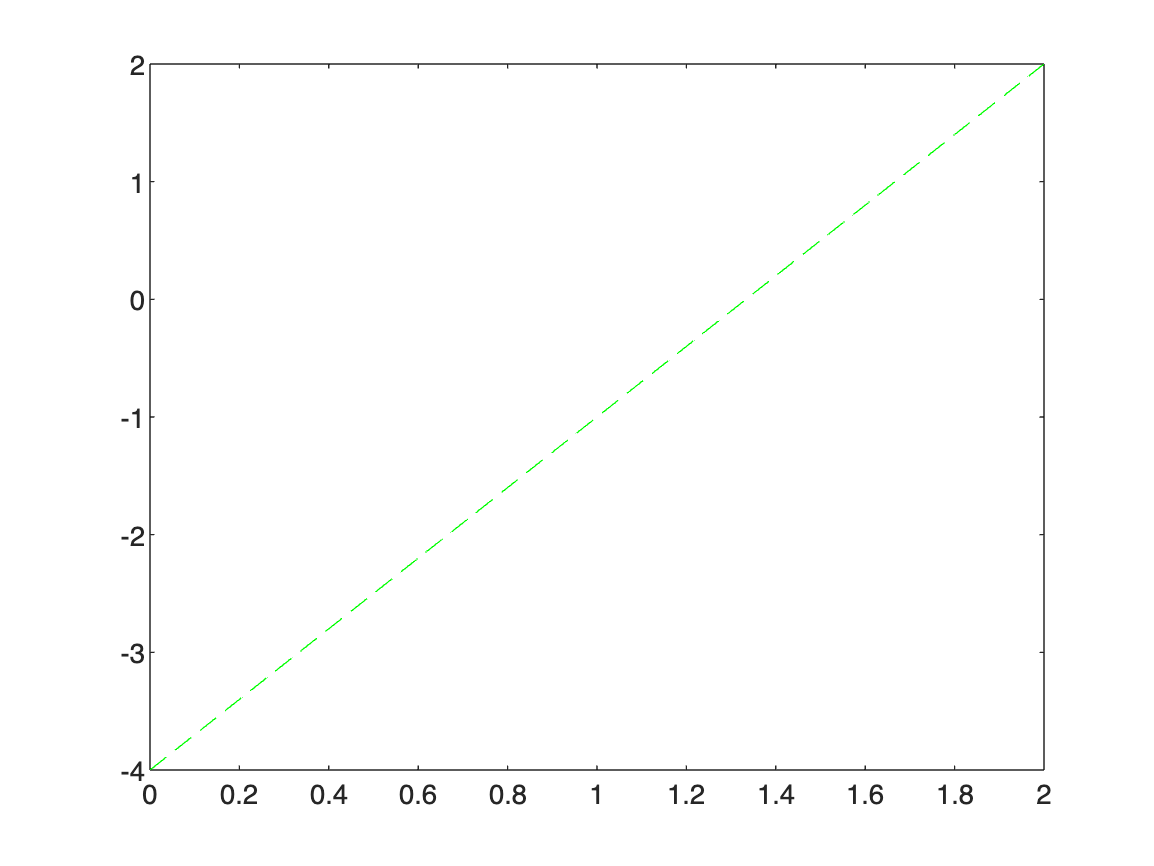

x = linspace(0,2,1000);
y = 3 * x - 4;
plot(x, y, "--g") % Plot y = 3x-4 in a green dashed line

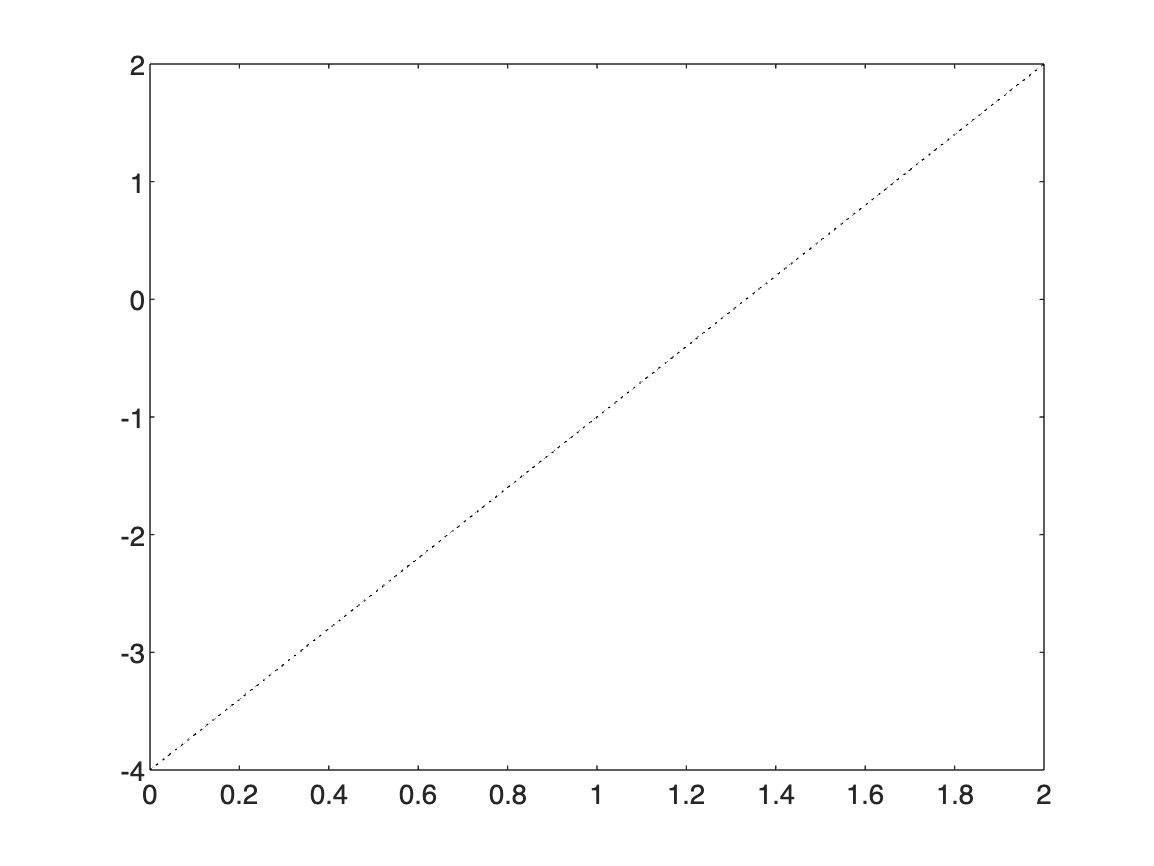

plot(x, y, ":k") % Black dotted line

We can also include titles for the x axis and y axis with the `xlabel` and `ylabel` commands, and a title for the graph with the `title` command. Make sure to surround your titles in quotation marks!

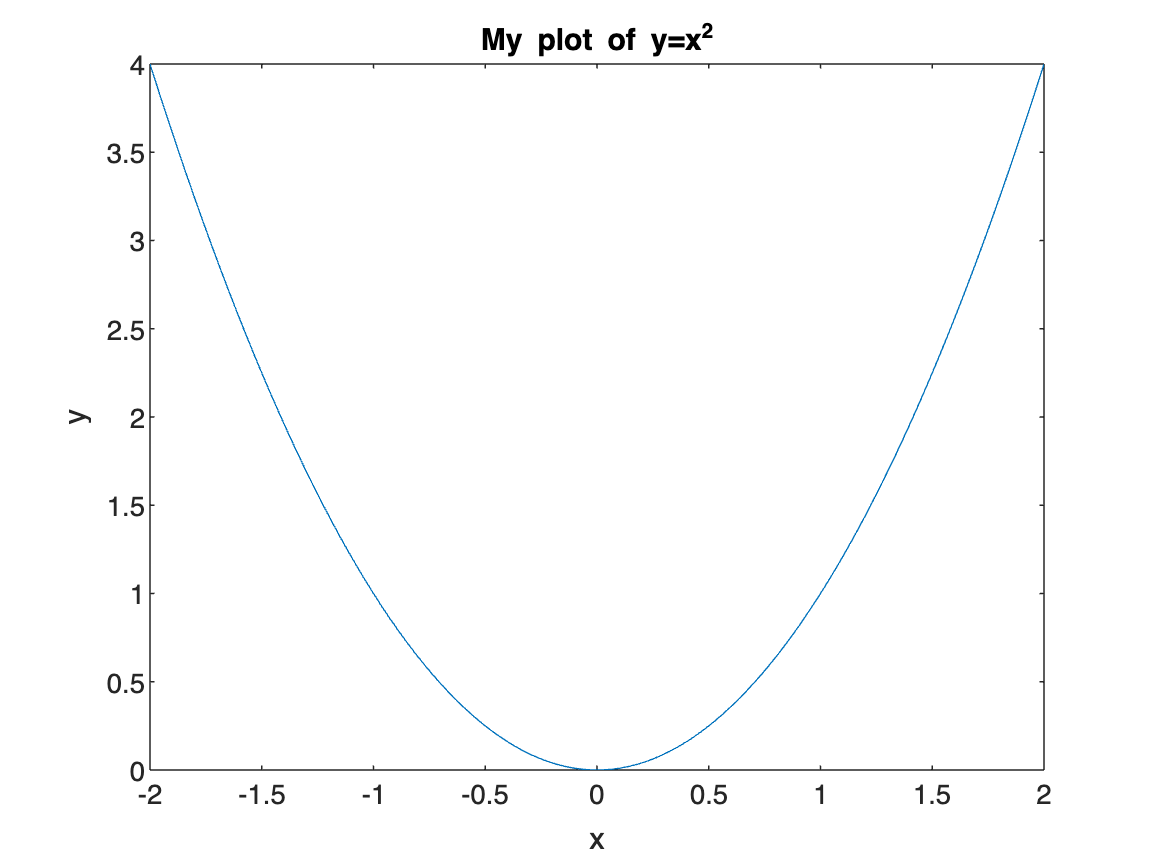

x = linspace(-2, 2, 1000);
y = x .^ 2;
plot(x, y) % y = x^2 (notice the dot!)
xlabel("x") % x axis title
ylabel("y") % y axis title
title("My plot of {y=x^2}") % Graph title - renders limited LaTeX! Use {...}

We can also plot multiple graphs on the same set of axes. To do this, we use the `hold on`` command`. This command tells MATLAB to plot everything on the same set of axes until it's told to stop (with the `hold off` command).

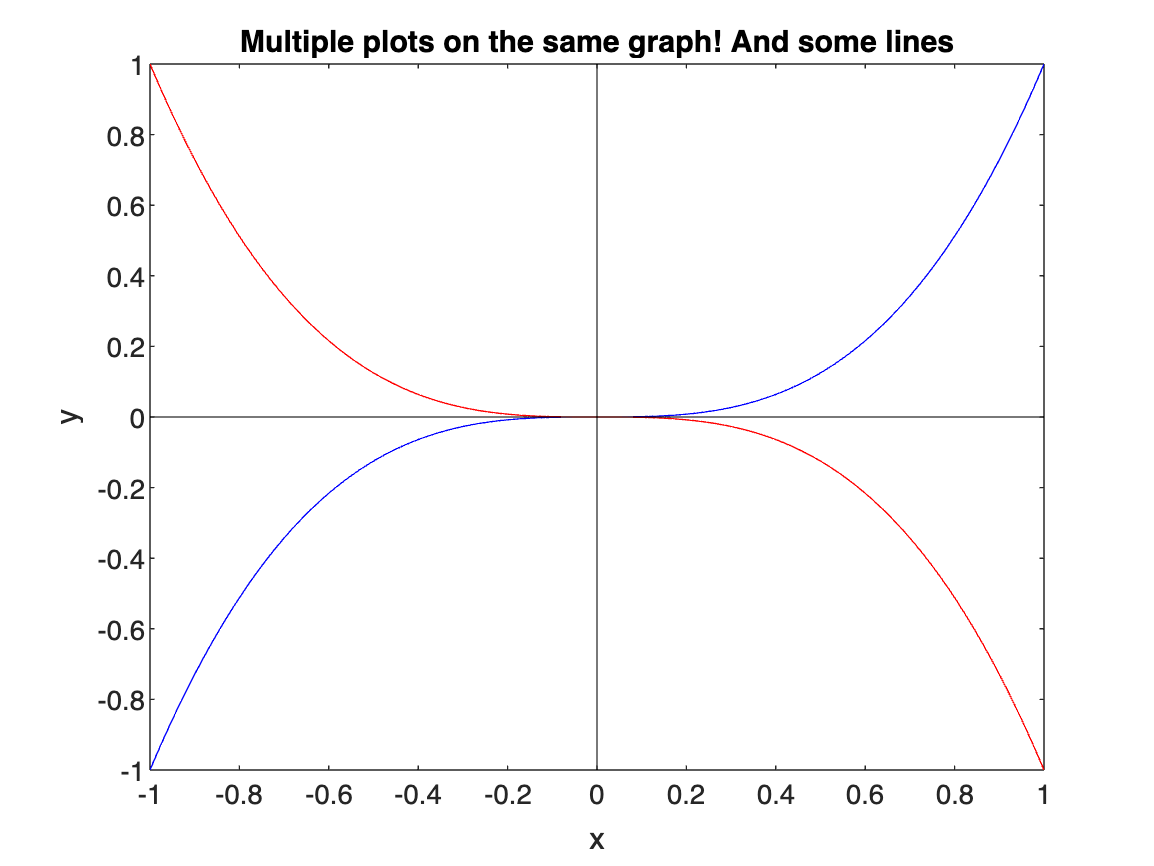

x = linspace(-1, 1, 1000);
y1 = x .^ 3;
y2 = -x .^ 3;

plot(x, y1, "-b")

hold on

plot(x, y2, "-r")

yline(0, "-k") % New command! Draws a horizontal line at y = 0
xline(0, "-k") % Draws a vertical line at x = 0

xlabel("x")
ylabel("y")
title("Multiple plots on the same graph! And some lines")

hold off % Make sure to include this line! Otherwise you might start plotting things together that you don't want

## *Your Turn!*

Let's plot the trajectory of our ball. Recall that we've stored our x coordinates and y coordinates in the vectors `calculated_x` and `calculated_y`. The theoretical maximum height is stored in the variable `maximum_height`.

Create a plot of the trajectory of the ball in a solid blue line, complete with appropriate labels for the x and y axes, and a title. On the same set of axes, plot a red dashed horizontal line at the height of the theoretical maximum height.

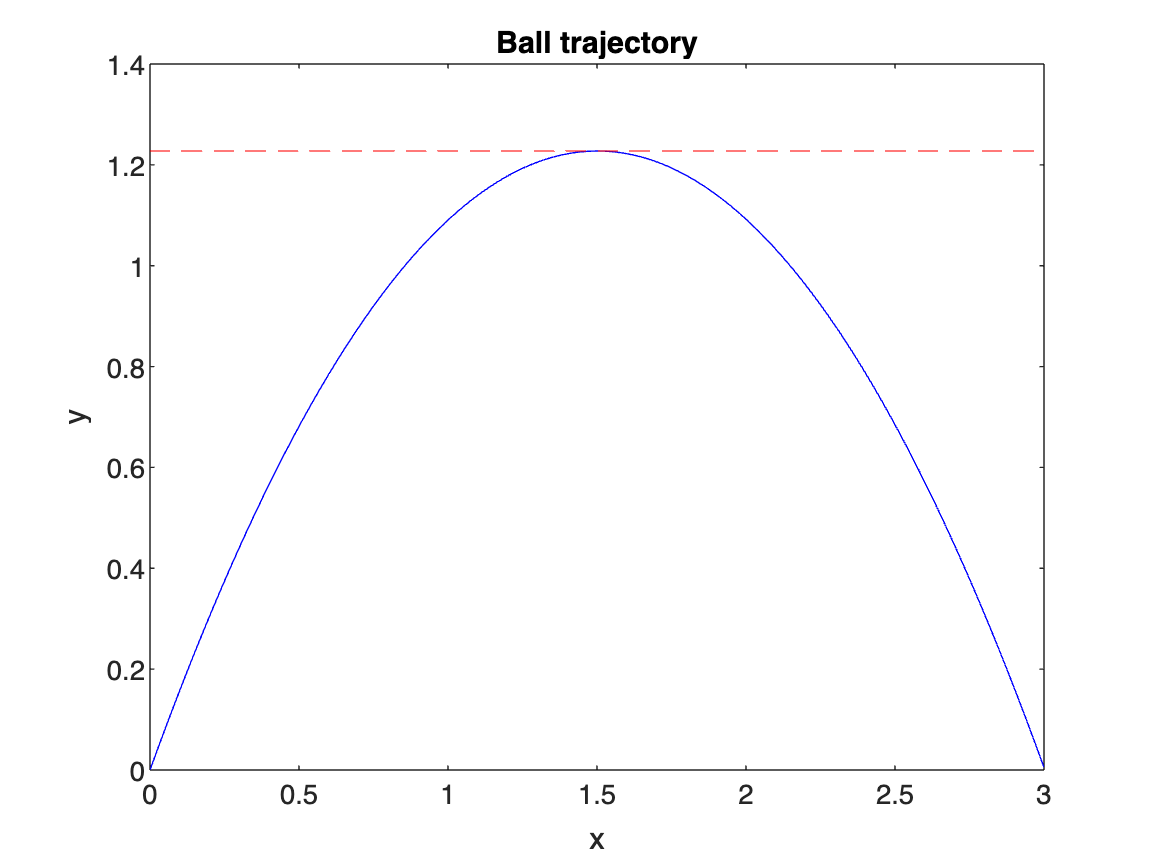

% Write your code below!
plot(calculated_x, calculated_y, "-b")
xlabel("x")
ylabel("y")
title("Ball trajectory")
hold on
yline(maximum_height, "--r")
hold off

A quick aside before we continue: MATLAB features a lot of plot types. For 3D plots, we can use the `surf` command. However, because this is now a function of both x and y, we need to use `meshgrid` to create a *matrix* of input values (rather than just a vector).

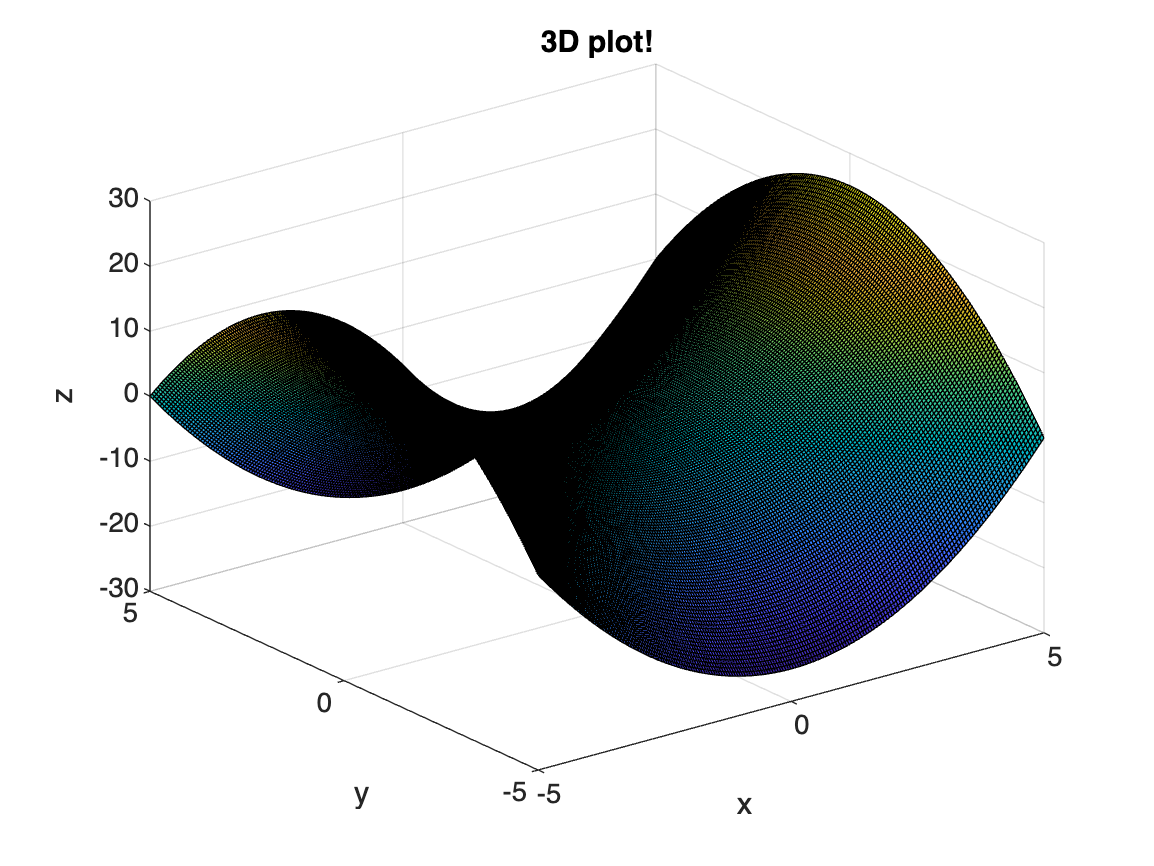

[x, y] = meshgrid(-5:0.05:5, -5:0.05:5); % Create x and y input values
z = x .^ 2 - y .^ 2;

surf(x, y, z) % Surface plot of z = x^2 - y^2. It kinda looks like a pringle

xlabel("x")
ylabel("y")
zlabel("z") % There's also z axis titles!
title("3D plot!")

## 6. ODE Solvers

The final useful tool of MATLAB we're going to cover is its collection of ODE solvers. Specifically, we are going to use the ODE solver `ode45`. MATLAB offers a suite of other ODE solvers, but `ode45` is the most versatile. If you haven't done/aren't doing MATH1052 yet, you might not be familiar with ODEs, so you can safely skip this section.

The `ode45` algorithm is based on a numerical method of solving ODEs called an explicit Runge-Kutta method. It solves ODEs of the form


$$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)$$


with an initial condition $y\left(0\right)=y_0$. It can be a bit confusing at first to use `ode45`, but hopefully we can step our way through it.

First, we create an *anonymous function*. This is essentially a function that doesn't have a name (so we can assign it one ourselves!). This anonymous function takes in two inputs: `t` and `y`, and outputs the value of the derivative. For example, if we have the ODE $y^{\prime } =2t$, we would write

dydt = @(t, y) 2 * t; % Assigns the function f(t,y) = 2t to the variable dydt

Next, we specify the *domain* of our time variable `t`. This is done with a vector that contains the start and end points.

tspan = [0 5]; % Describes the endpoints of our domain

Finally, we specify an initial condition. 

y0 = 0; % Initial condition

We finally have the setup to numerically solve our ODE. We use the `ode45` command like this:

[t, y] = ode45(dydt, tspan, y0);

This will output two vectors: `t` gives us all the points in time the solver used to sample, and `y` gives us the value of the solution at each corresponding sample point. Getting the output in this form is helpful because it allows us to easily plot the data.

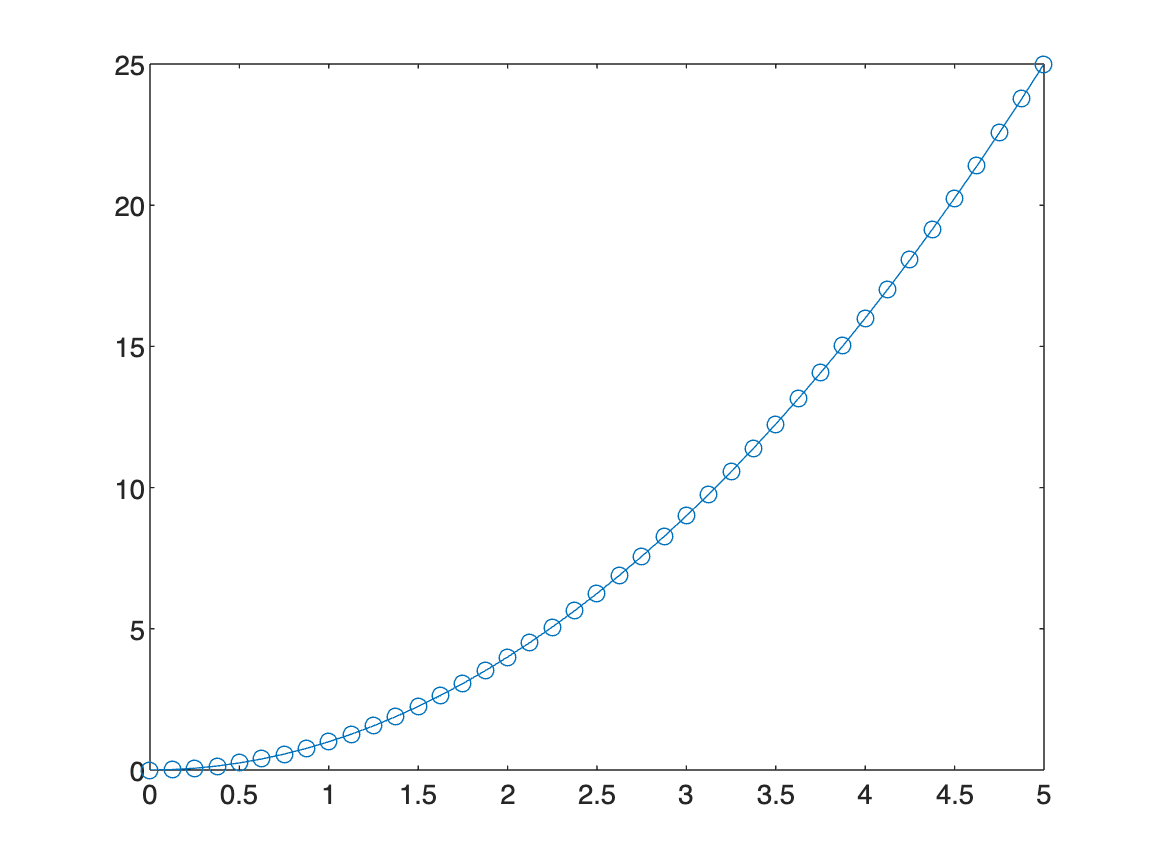

plot(t, y, "-o") % The o condition puts a circle at each sample point

## 7. Solving higher-order ODEs

One big downside of `ode45` is that it can only solve first-order ODEs. Not to worry! It's actually possible to write any *n*th-order ODE as a system of *n* coupled first-order ODEs. We won't bore you with the details, but essentially we define new variables as successive derivatives (think of position, velocity, acceleration, etc). Let's say we have the second-order ODE ${y^{\prime } }^{\prime } =6y^{\prime } -13y$. We would define the variable $u=y^{\prime }$, so that the second-order ODE becomes $u^{\prime } =6u-13y$. This gives us a system of ODEs:


$$\left\lbrace \begin{array}{ll}
y^{\prime } =u, & \\
u^{\prime } =6u-13y\ldotp  & 
\end{array}\right.$$


In this form, `ode45` is able to solve it! This is even more confusing than last time, but we can push through!

First, let's define `dydt` like last time. It's a little bit different now that we have a system of ODEs. The `y` input in the anonymous function is actually a vector of all our new variables!


$$Y=\left\lbrack \begin{array}{c}
y\\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
Y\left(1\right)\\
Y\left(2\right)
\end{array}\right\rbrack \ldotp$$


We need to specify our `dydt` vector in the form


$$\textrm{dydt}=\left\lbrack \begin{array}{c}
y^{\prime } \\
u^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u\\
6u-13y
\end{array}\right\rbrack \ldotp$$


dydt = @(t, Y) [Y(2); 6 * Y(2) - 13 * Y(1)]; % The ODEs are y' = u = Y(2), and u' = 6u - 13y = 6*Y(2) - 13*Y(1)
% Notice that this is a column vector!

Defining `tspan` is the same as before.

tspan = [0 3];

The initial conditions are a little different. As we have two variables, we need two initial conditions.

Y0 = [0; 1]; % We now have to specify two initial conditions: one for y(0) and one for u(0) = y'(0).

We are finally ready to use `ode45`! Let's solve the ODE numerically and plot the solution.

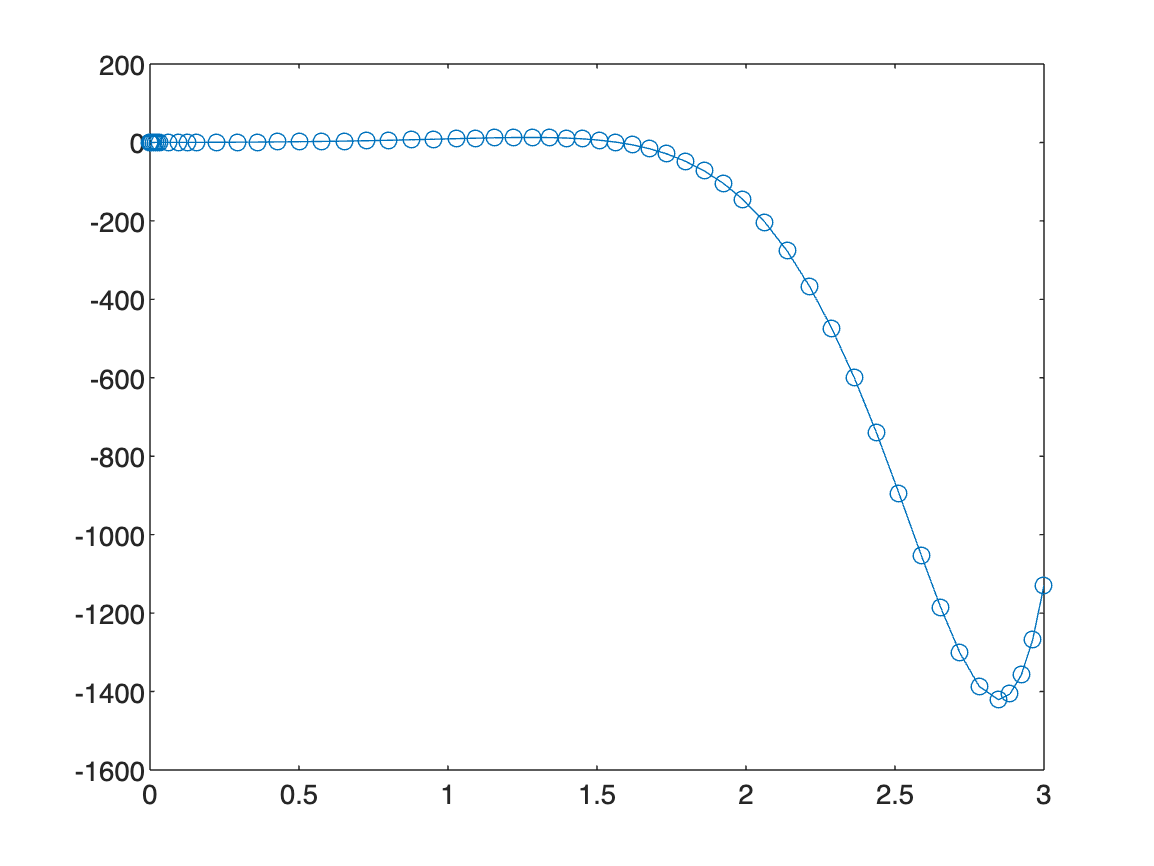

[t, Y] = ode45(dydt, tspan, Y0); % Y returns as a matrix - the first column is the solution to y, and the 
% second column is the solution to u
plot(t, Y(:, 1), "-o") % We only care about the solution to y, so we retrieve the first column using colon-indexing

## *Your Turn!*

This is the final exercise! We've almost completed the model for our ball's trajectory. The last thing that's left to do is simulate the trajectory based on the equation of motion (a second-order ODE).

The only force acting on the ball is gravity (in the vertical direction). There are no forces in the horizontal direction. This gives us two ODEs:

${x^{\prime } }^{\prime } =0$, $\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{y^{\prime } }^{\prime } =-g$.

First, convert both of these ODEs into systems of first-order ODEs. Then, use `ode45` to solve the ODE on the domain $[0,1]$ and plot the simulated solution with initial conditions $x(0)=y(0)=0$ and $x'(0)=u_x$ and $y'(0)=u_y$ (remember that these are stored in the variables `initial_x_velocity` and `initial_y_velocity`). Also plot your calculated trajectory (`calculated_x` and `calculated_y`) on the same set of axes in a black line, and see how well it matches up!

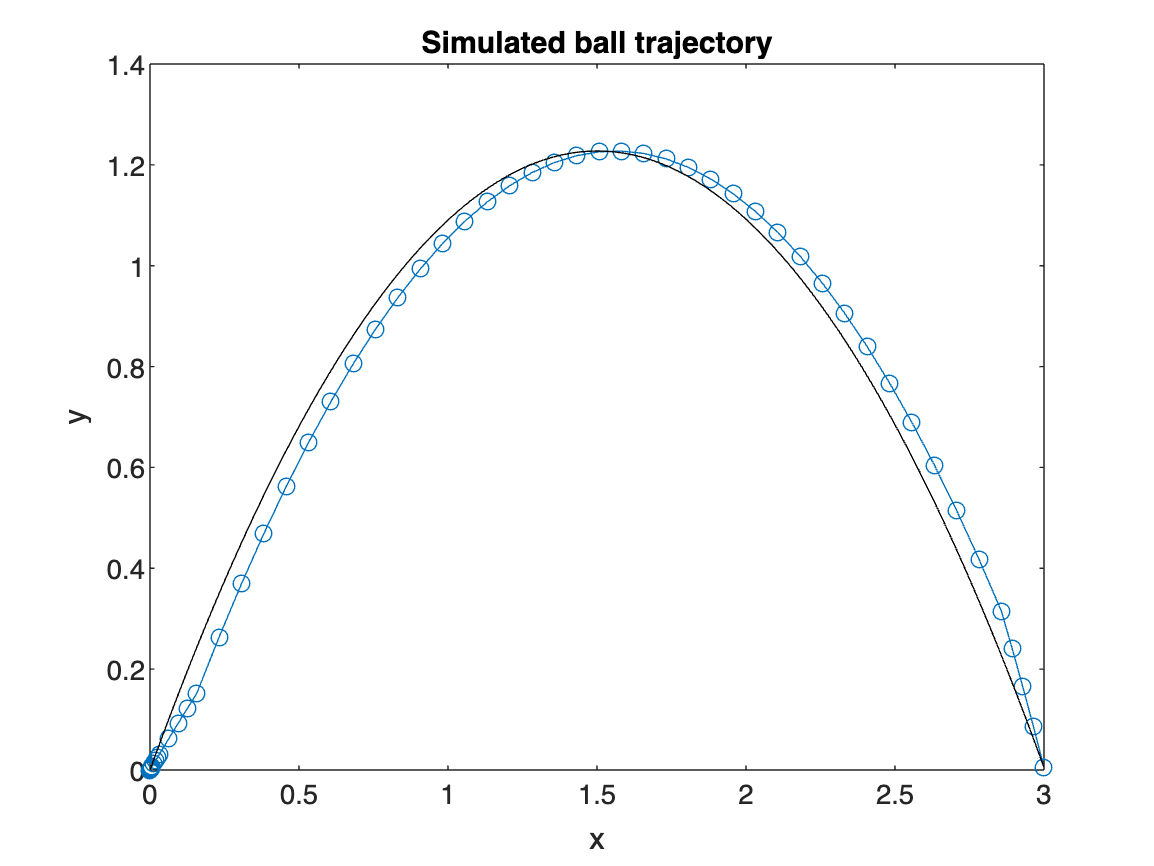

% Your code here!
dxdt = @(t, X) [X(2); 0];
dydt = @(t, Y) [Y(2); -g];

tspan = [0 1];

X0 = [0; initial_x_velocity];
Y0 = [0; initial_y_velocity];

[t, simulated_x] = ode45(dxdt, tspan, X0); % You will need to run ode45 twice - once for x
[t, simulated_y] = ode45(dydt, tspan, Y0); % and once for y

% This isn't exactly how you're supposed to do it (the t vectors are
% different for each simulation so the plot is slightly skewed), but having
% a system of 4 coupled ODEs is a bit too much here. Maybe students can try
% and figure out why it doesn't match up exactly?

plot(simulated_x(:, 1), simulated_y(:, 1), "-o")
xlabel("x")
ylabel("y")
title("Simulated ball trajectory")
hold on
plot(calculated_x, calculated_y, "-k")
hold off

Now, let's add an air resistance term! We now have a force in the horizontal direction opposing the motion of the ball. This would be a lot harder to compute manually. Luckily, we can numerically solve the ODE! Air resistance adds an extra force in each direction, and is proportional to the velocity squared. The ODEs are now

${x^{\prime } }^{\prime } =-{k\left(x^{\prime } \right)}^2$, $\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{y^{\prime } }^{\prime } =-g-{k\left(y^{\prime } \right)}^2$,

where $k$ is a constant depending on the air resistance. Convert both of these ODEs into systems of first-order ODEs. Then, use `ode45` to solve the ODE on the domain $[0,1]$ and plot the simulated solution, with initial conditions $x(0)=y(0)=0$ and $x'(0)=u_x$ and $y'(0)=u_y$. Use the constant $k=0.4$. Plot the calculated trajectory on the same set of axes in a black line. What do you notice?

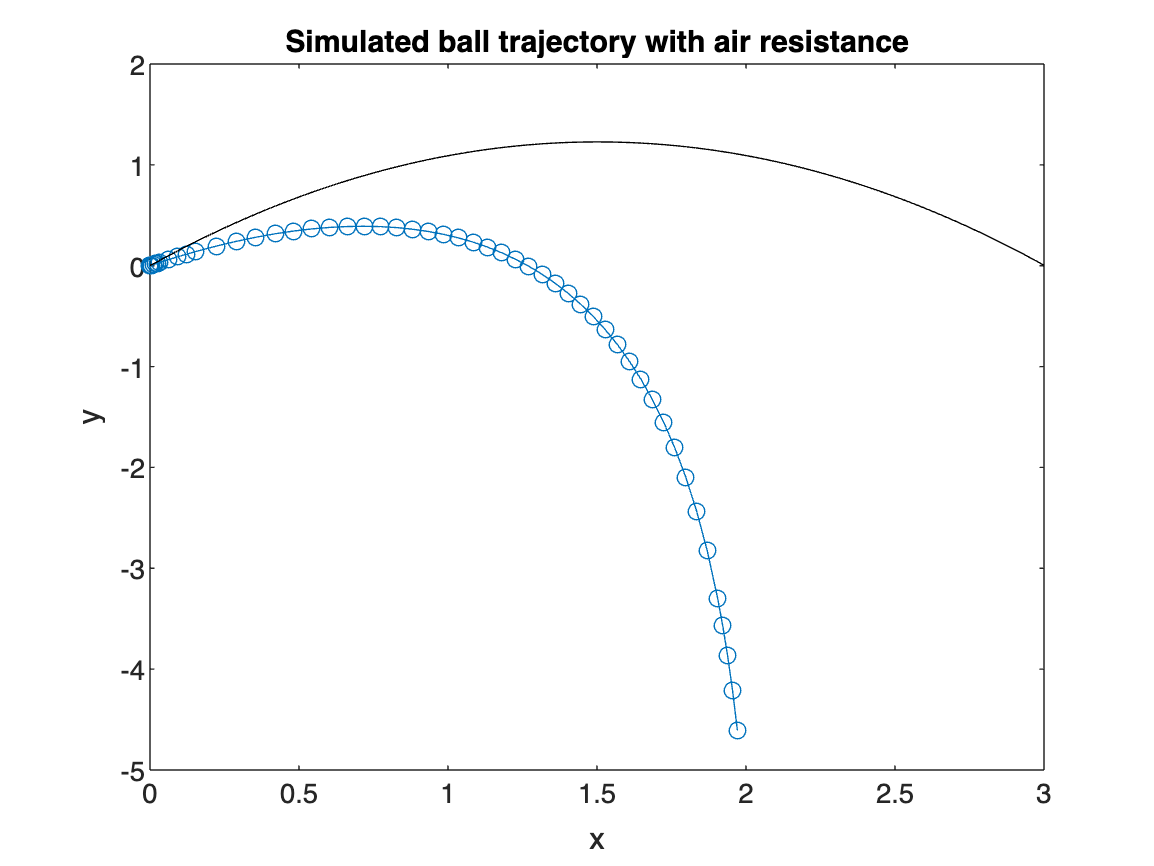

% Your code here!
k = 0.4;

dxdt = @(t, X) [X(2); -k * X(2) ^ 2];
dydt = @(t, Y) [Y(2); -g - k * Y(2) ^ 2];

tspan = [0 1];

X0 = [0; initial_x_velocity];
Y0 = [0; initial_y_velocity];

[t, simulated_x] = ode45(dxdt, tspan, X0);
[t, simulated_y] = ode45(dydt, tspan, X0);

plot(simulated_x(:, 1), simulated_y(:, 1), "-o")
xlabel("x")
ylabel("y")
title("Simulated ball trajectory with air resistance")
hold on
plot(calculated_x, calculated_y, "-k")
hold off

## Thank You!

Thank you for coming along to this MATLAB refresher. We hope you enjoyed learning about MATLAB and its uses in plotting functions and solving ODEs.

% Ignore this, it just suppresses a warning :)
%#ok<*IJCL>
%#ok<*ASGLU>
%#ok<*FNDSB>